Made by Nicolas SALVAN `(S6155197)`

# PID Control - Tuning

This notebook is dedicated to the tuning of the PID controler for different models of bird flying on a plane. I will only study the linearized system. 

## Preliminary calculations

s = tf('s'); % variable used for the transfer function 

# Linearized Problem - Control over $\theta$

## 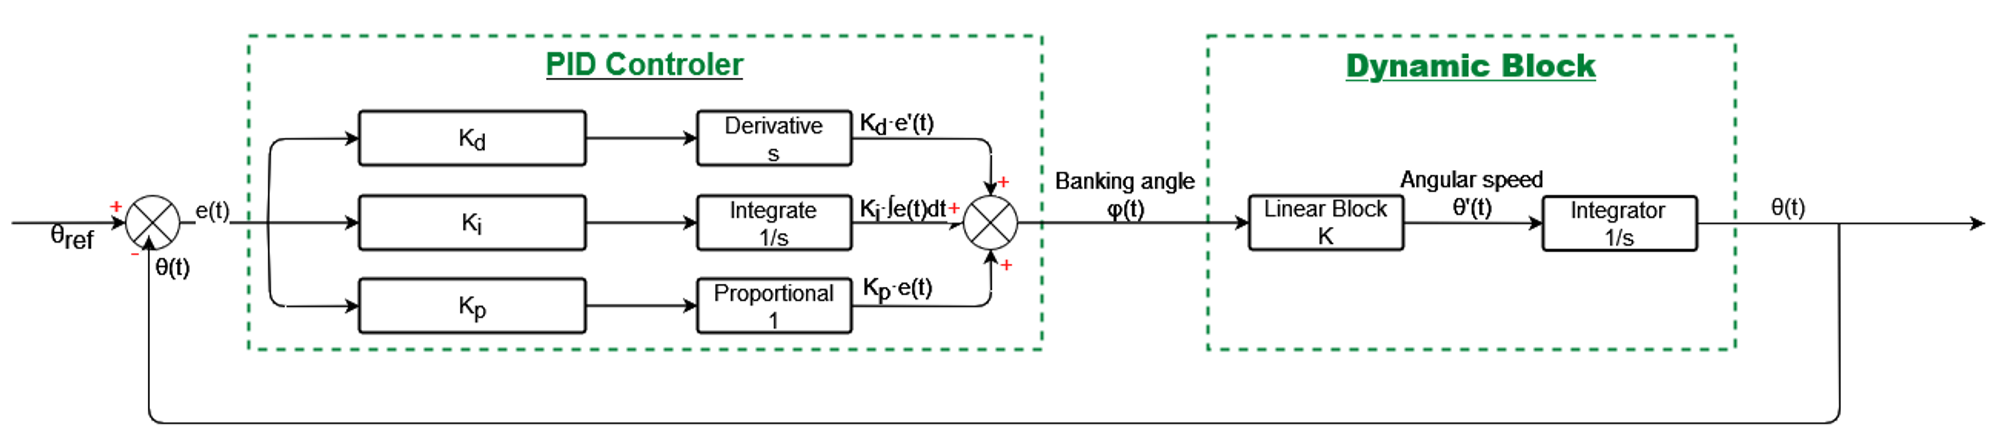

## Create the plant system

% Define the open-loop system 
sys = 1/s;

## PID Tuning Options

% options = pidtuneOptions('CrossoverFrequency', 10, ...  
%                          'PhaseMargin', 60, ...         
%                          'DesignFocus', 'reference-tracking'); 
options = pidtuneOptions('CrossoverFrequency',10) ;


## PID tuning with `pidtune`

% Tuning PID Controler
% [C_pid, info] = pidtune(sys, 'PID', options);
[C_pid, info] = pidtune(sys, 'PID');


Let's show the different parameters of the PID Controler. 

Kp =    C_pid.Kp

Kp = 0.9812

Ki = C_pid.Ki

Ki = 0.1929

Kd = C_pid.Kd

Kd = 0

We can also show bandwidth and phase margin information.

info 

info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1
           PhaseMargin: 78.8791


## Closed loop with the PID Controler

closed_loop_sys = feedback(C_pid * sys, 1);

## Step response of the closed loop system

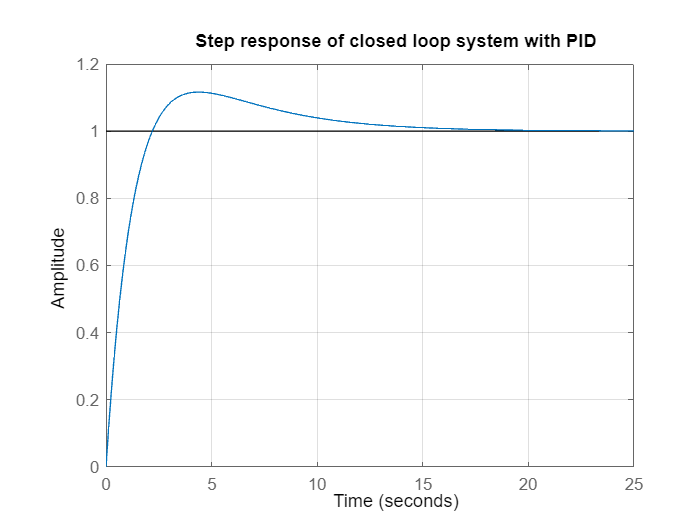

figure;
step(closed_loop_sys);
title('Step response of closed loop system with PID');
grid on;

% Get the characteristics of the step response
info = stepinfo(closed_loop_sys)

info = struct with fields:
         RiseTime: 1.5687
    TransientTime: 12.5996
     SettlingTime: 12.5996
      SettlingMin: 0.9031
      SettlingMax: 1.1164
        Overshoot: 11.6370
       Undershoot: 0
             Peak: 1.1164
         PeakTime: 4.4150


**Interpretation : **??? 

## Bode plot for gain and phase margin analysis 

[gm, pm, wg, wp] = margin(closed_loop_sys); % Compute phase and gain margins
gm % Gain margin in dB 

gm = Inf

pm % Phase margin in degrees 

pm = 144.8790

wg % Frequency at the gain margin, in rad/s

wg = NaN


wp % Frequency at the phase margin, in rad/s

wp = 0.6210

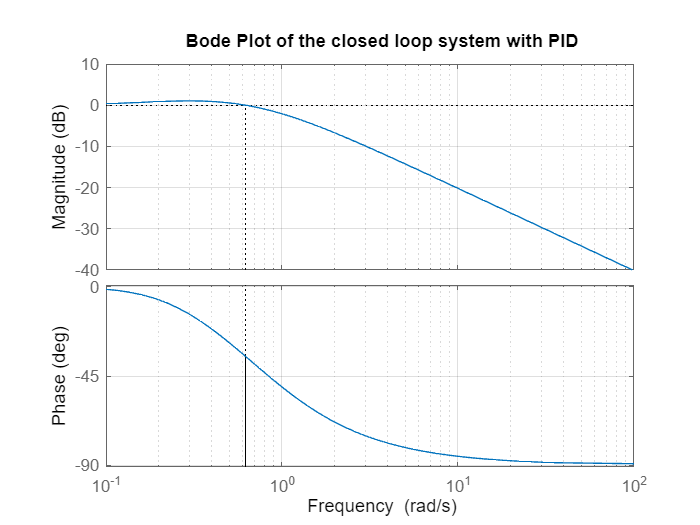

figure;
margin(closed_loop_sys);
title('Bode Plot of the closed loop system with PID');
grid on;

**Interpretation : **(margins, ...) 

## Nyquist plot for the study of stability

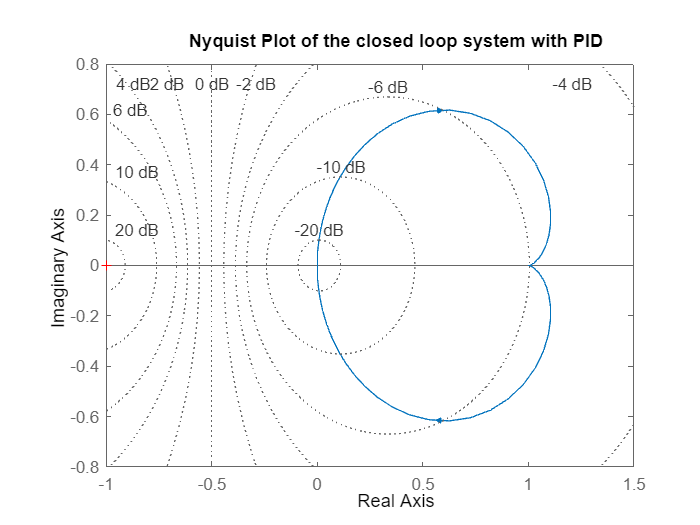

figure;
nyquist(closed_loop_sys);
title('Nyquist Plot of the closed loop system with PID');
grid on;

**Interpretation : **(Nyquist Criterion, etc.) 

## Sensitivity function

S = 1/(1+C_pid*sys)

S =
 
            s^2
  -----------------------
  s^2 + 0.9812 s + 0.1929
 
Continuous-time transfer function.
Model Properties


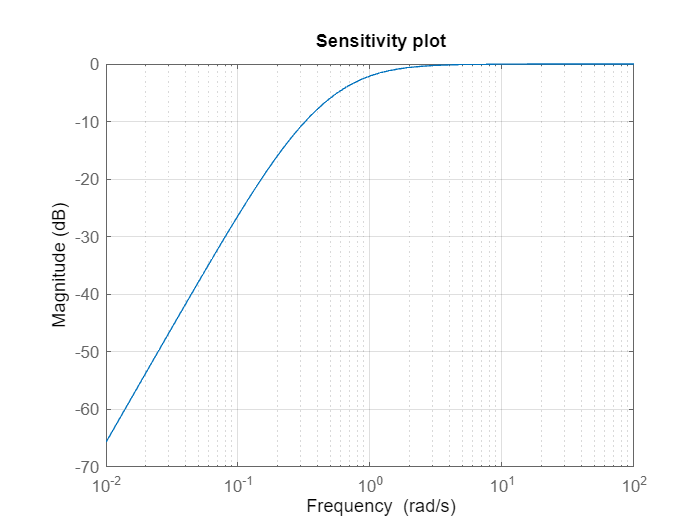


figure;
bodemag(S);
title('Sensitivity plot');
grid on;

##  Poles and zeros of the transfer function

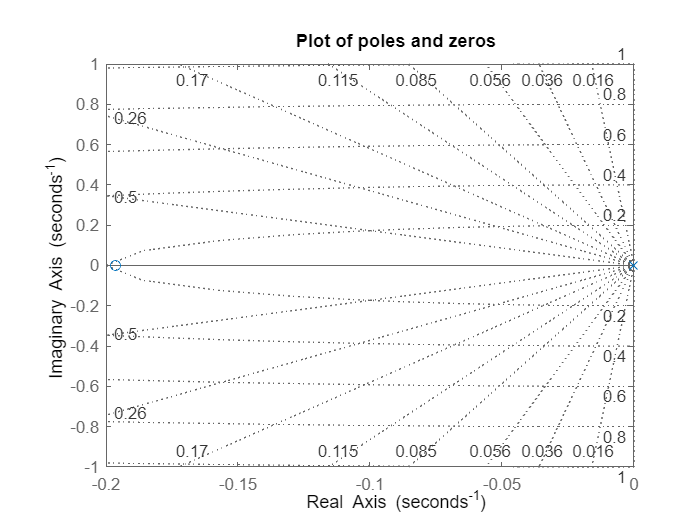

% Tracer les pôles et les zéros
figure;
pzmap(sys * C_pid);
title('Plot of poles and zeros');
grid on;

## Root Locus Analysis

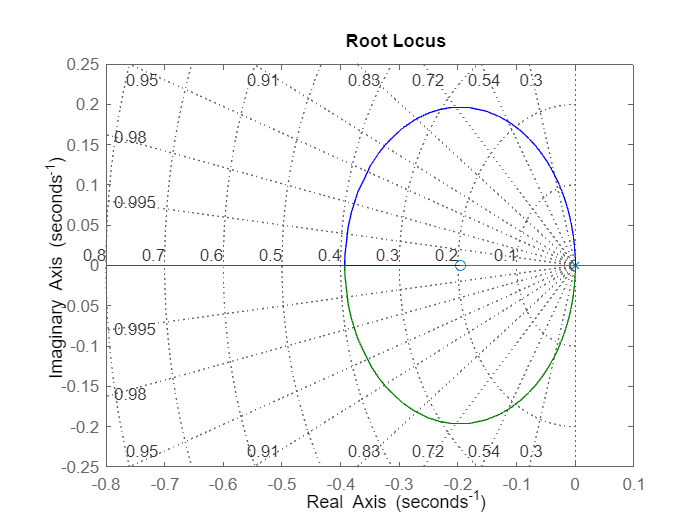

% Tracer le lieu des racines
figure;
rlocus(sys * C_pid);
title('Root Locus');
grid on;

## Nichols Chart

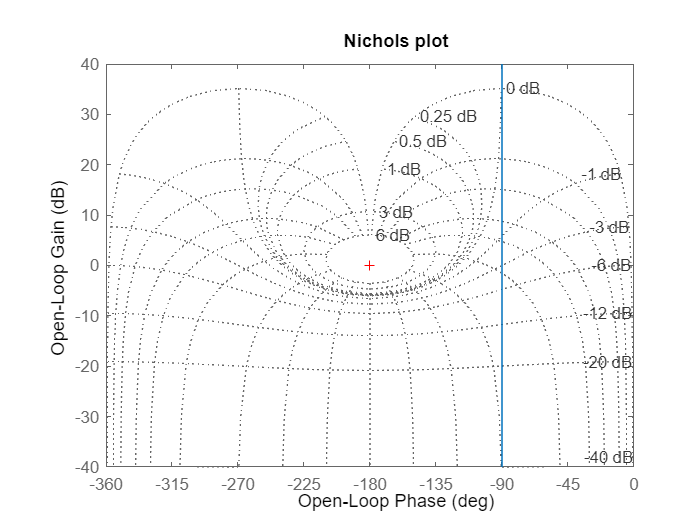

figure;
nichols(sys);
title('Nichols plot');
grid on;